clc; clear; close all;

%[lyd,Fs] = audioread("﻿/Users/caspertk/Library/CloudStorage/OneDrive-AalborgUniversitet/4. semester/Projekt/Kode/ingridfinder7roedehuse.wav")
[lyd,Fs] = audioread("/Users/caspertk/Desktop/ingridfinder7roedehuse.wav")

lyd =    -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000


Fs = 44100

%[lyd,Fs] = audioread("/Users/caspertk/Downloads/P2 - kode osv/Experiment_Optagelser_ægte.wav")
nylyd = downsample(lyd, 3);


## Opsætning af variable

cutoff = 1500; %beta i projektet
tfaktor = 500; %tau i projektet
alpha = 0.7;



## Opsætning af fft for signalet

%ori_fft = fft(nylyd,Fs/3)
ori_fft = fft(nylyd);
%plot(abs(ori1_fft))

original = abs(ori_fft(1:7350,:))

original =     1.1694
    0.6148
    1.0619
    0.6006
    0.7619
    0.8506
    0.8672
    0.2592
    0.8611
    0.7001


y1fft = ori_fft(1:cutoff,:)

y1fft = 	1.0e+02 *

  -0.0117 + 0.0000i
  -0.0045 + 0.0042i
   0.0015 - 0.0105i
   0.0033 + 0.0050i
  -0.0025 - 0.0072i
   0.0084 + 0.0015i
  -0.0085 + 0.0016i
  -0.0017 - 0.0020i
  -0.0016 - 0.0085i
   0.0049 - 0.0050i


y2fft = ori_fft(cutoff+1:7350,:)

y2fft =   -2.8991 + 1.6151i
   4.5338 - 1.2871i
  -4.6842 + 4.5325i
   1.0652 - 6.5503i
   1.0570 + 3.5796i
  -3.0201 - 5.7101i
   6.2934 + 5.6244i
  -7.5208 + 0.0730i
   6.8239 - 2.6097i
  -5.8609 + 5.4367i


y3fft = zeros([cutoff 1])

y3fft =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


y4fft = [zeros([cutoff 1]); y2fft]

y4fft =    0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i



y1 = abs(y1fft);
y2 = abs(y2fft);
y3 = abs(y3fft);
y4 = abs(y4fft);

a = abs(ori_fft);


## Nyt signal med implementation af begge




N = length(original)

N = 7350



aliste = (zeros(N, 1));
lyden = (zeros(N, 1));
listen = (zeros(N, 1));

for n = 1:N
    if n >= cutoff
        a = fix((n - tfaktor) * alpha(1));
        %a = fix((n * alpha(1)) - tfaktor);
        aliste(a) = aliste(a) + original(n);
        n1 = n;
    end
    for k = 1:N
        %listen(k) = aliste(k);
        %lyden(k) = aliste(k) + original(k);
        lyden(k) = aliste(k) + original(k);
    end
end




%subplot(2,2,1)
plot(original)
xline(cutoff,color='black',LineStyle='--',linewidth=1)
%title('Original signal')
xlim([0,7350])
xlabel('Frequency [Hz]', Fontsize = 18)
ylabel('Amplitude', Fontsize = 18)
lgd = legend('Original signal')

lgd =   Legend (Original signal) with properties:

         String: {'Original signal'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.7161 0.8702 0.1750 0.0357]
          Units: 'normalized'

  Show all properties


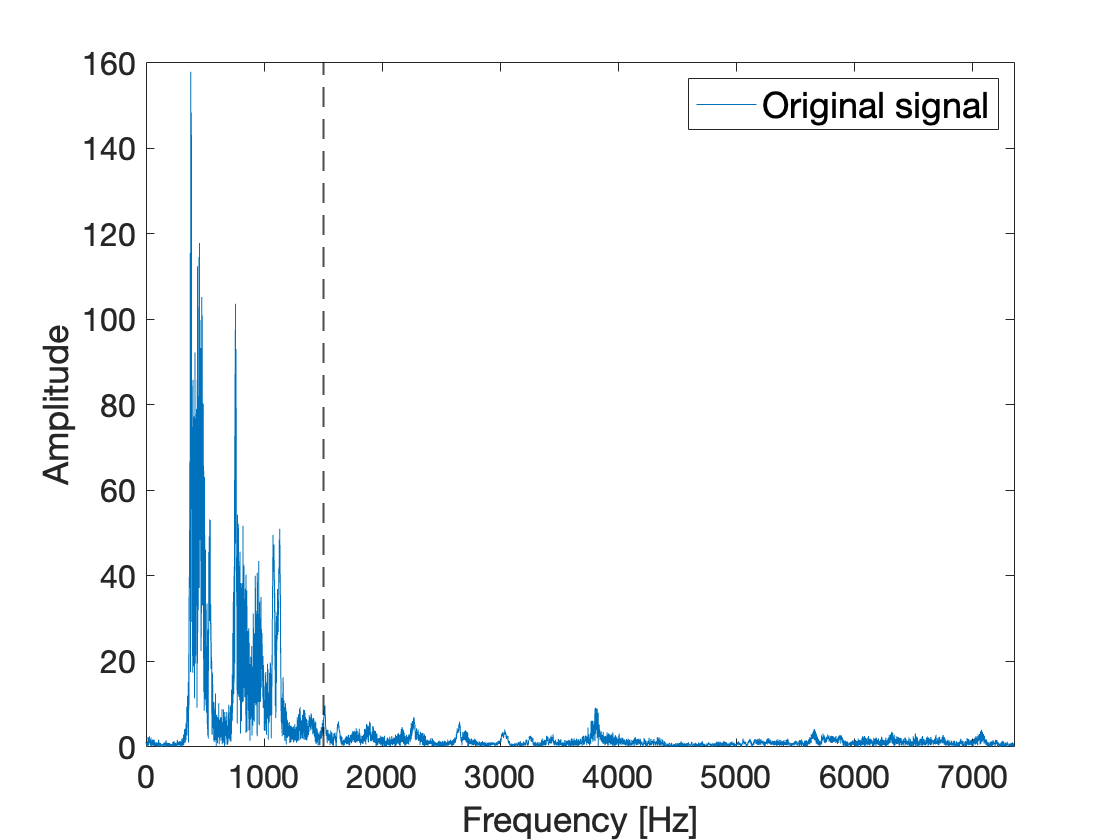

lgd.FontSize = 18;
set(gca, 'FontSize',16)
saveas(gcf,['/Users/caspertk/Library/CloudStorage/OneDrive-AalborgUniversitet/4. semester/Projekt/Kode/Both_plots1.png'])

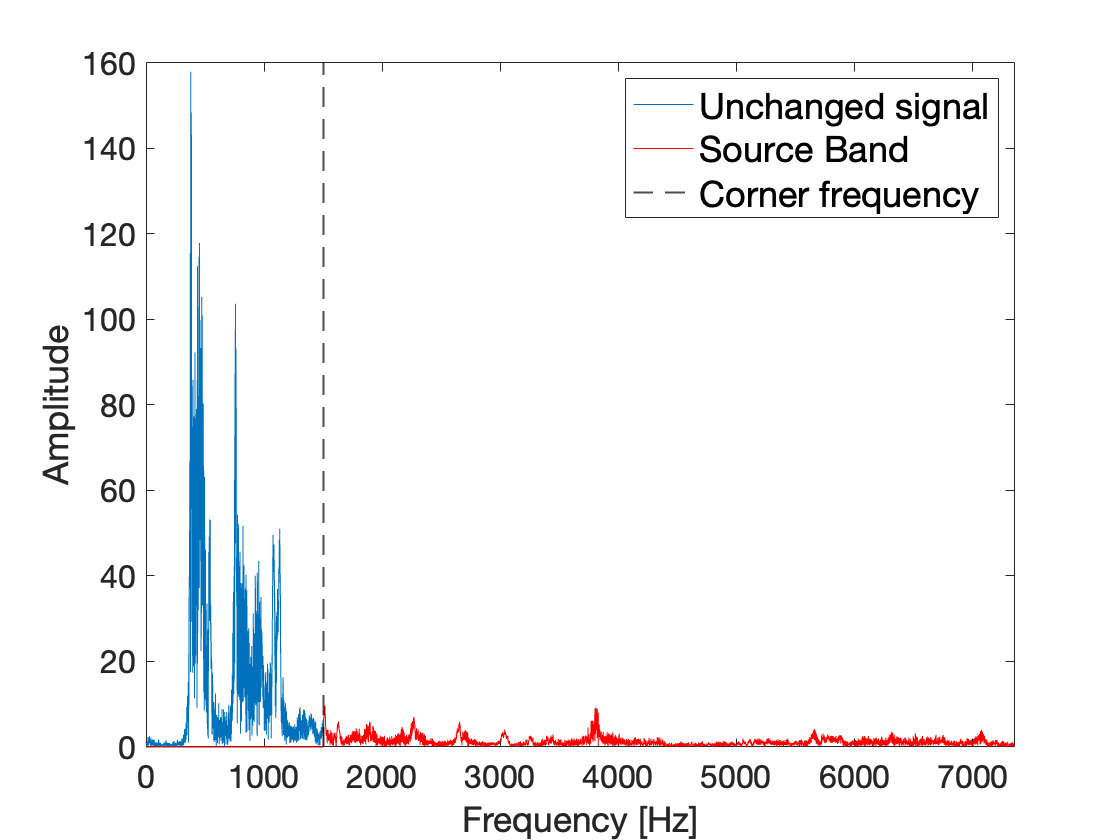




%subplot(2,2,2)
plot(y1)
hold on
plot(y4, color='red')
xline(cutoff,color='black',LineStyle='--',linewidth=1);
%title('Original signal splittet')
xlim([0,7350])
legend('Unchanged signal', 'Source Band', 'Corner frequency', FontSize = 18)
xlabel('Frequency [Hz]', Fontsize = 18)
ylabel('Amplitude', Fontsize = 18)
set(gca, 'FontSize',16)
hold off
saveas(gcf,['/Users/caspertk/Library/CloudStorage/OneDrive-AalborgUniversitet/4. semester/Projekt/Kode/Both_plots2.png'])

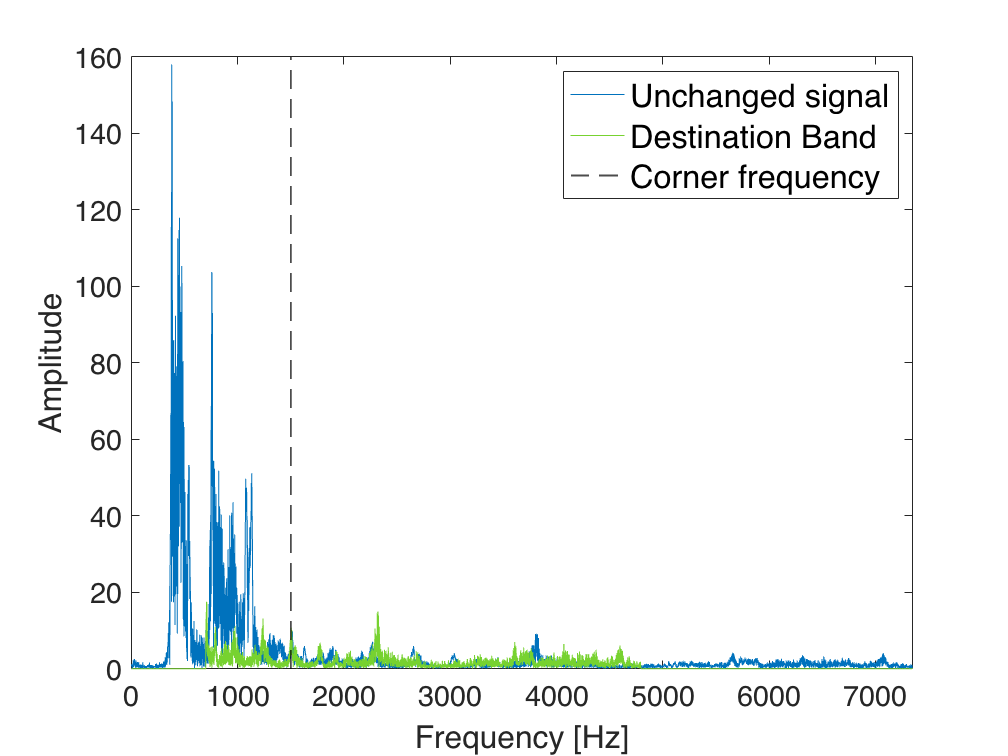



%subplot(2,2,3)

green = [0.4660 0.8240 0.1880];

plot(original)
hold on
plot(aliste, color= green)
xline(cutoff,color='black',LineStyle='--',linewidth=1);
%title('Original signal splittet')
xlim([0,7350])
legend('Unchanged signal', 'Destination Band','Corner frequency', FontSize = 18)
xlabel('Frequency [Hz]', Fontsize = 18)
ylabel('Amplitude', Fontsize = 18)
set(gca, 'FontSize',16)
hold off
saveas(gcf,['/Users/caspertk/Library/CloudStorage/OneDrive-AalborgUniversitet/4. semester/Projekt/Kode/Both_plots3.png'])

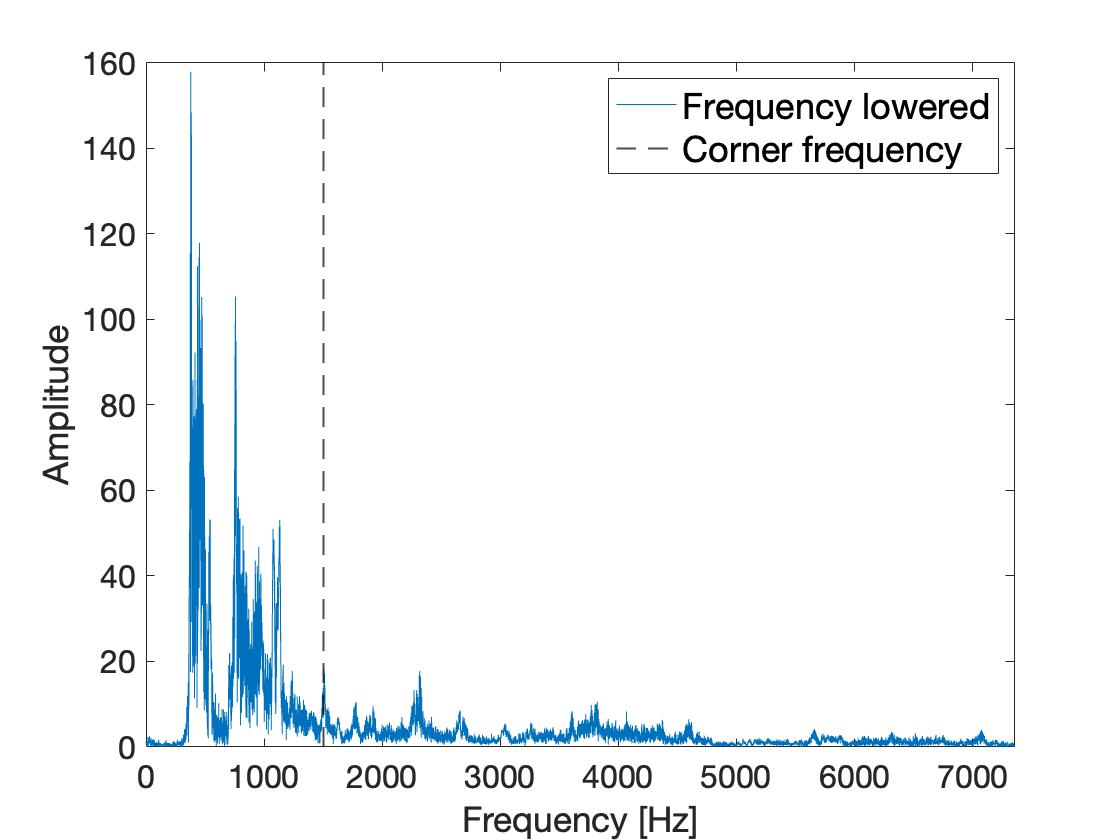




%subplot(2,2,4)

plot(lyden)
%title('Frequency Plot')
xline(cutoff,color='black',LineStyle='--',linewidth=1);
%title('Original signal splittet')
xlim([0,7350])
legend('Frequency lowered', 'Corner frequency', FontSize = 18)
xlabel('Frequency [Hz]', Fontsize = 18)
ylabel('Amplitude', Fontsize = 18)
set(gca, 'FontSize',16)
saveas(gcf,['/Users/caspertk/Library/CloudStorage/OneDrive-AalborgUniversitet/4. semester/Projekt/Kode/Both_plots4.png'])